%% 8. MODEL DIAGNOSTICS & VIF ANALYSIS (SEPARATE FOR EACH MODEL)
fprintf('10. Generating Model Diagnostics and VIF for each model...\n');

10. Generating Model Diagnostics and VIF for each model...


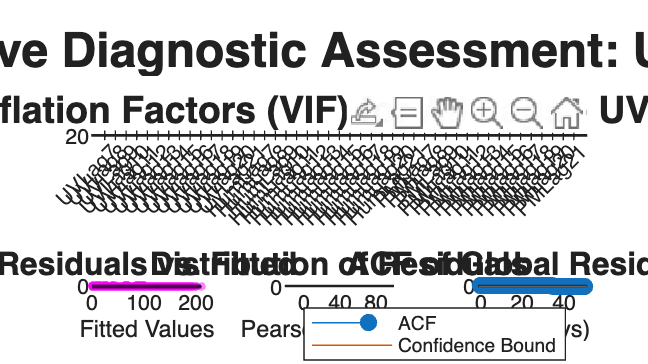

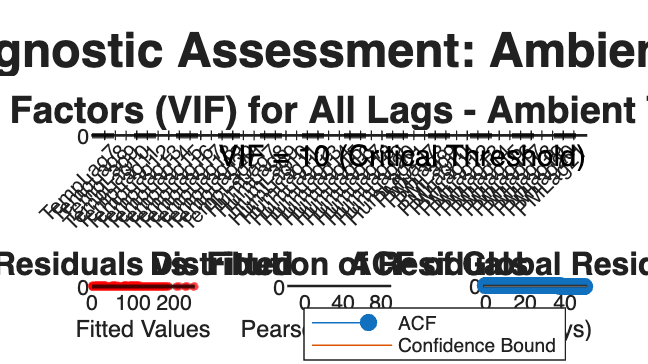

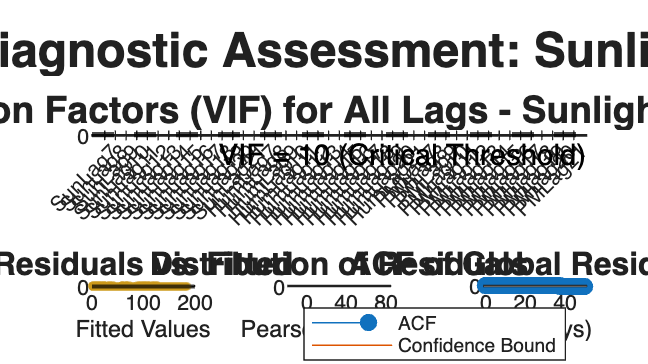


mdls = {M3_UV_mdl, M3_Temp_mdl, M3_Sun_mdl};
mdl_names = {'UV Index', 'Ambient Temperature', 'Sunlight Duration'};
var_lags_list = {U_Lags, T_Lags, S_Lags};
var_names_list = {U_Names, T_Names, S_Names};
colors = {'m', 'r', [0.8 0.6 0.1]};

% PDF dosyası için hazırlık
pdf_filename = 'Model_Diagnostics_and_VIF.pdf';
if exist(pdf_filename, 'file')
    delete(pdf_filename);
end

for m = 1:3
    % --- A. VIF (VARIANCE INFLATION FACTOR) HESAPLAMASI ---
    % O modele giren tüm çevresel gecikmeleri (Ana Sinyal + Nem + PM2.5) birleştiriyoruz
    X_vif = [var_lags_list{m}, H_Lags, P_Lags];
    VIF_Names = [var_names_list{m}, Hum_Names, PM25_Names];
    
    valid_vif_idx = ~any(isnan(X_vif), 2);
    X_vif_clean = X_vif(valid_vif_idx, :);
    
    % MATLAB'de VIF hesabı: Korelasyon matrisinin tersinin köşegen elemanlarıdır
    R_vif = corrcoef(X_vif_clean);
    VIF_values = diag(inv(R_vif));
    
    % --- B. RESIDUAL (ARTIK) DEĞERLERİ ÇEKME ---
    res_current = mdls{m}.Residuals.Pearson;
    fit_current = mdls{m}.Fitted.Response;
    
    % ACF için küresel ortalama artıkları güne göre hesaplıyoruz
    dates_uniq = unique(T_Base.Time);
    global_res = zeros(length(dates_uniq), 1);
    for i = 1:length(dates_uniq)
        global_res(i) = mean(res_current(T_Base.Time == dates_uniq(i)), 'omitnan');
    end
    
    % --- C. FİGÜR OLUŞTURMA ---
    fig = figure('Name', sprintf('Diagnostics: %s Model', mdl_names{m}), 'Color', 'w', 'Position', [100 100 1600 900]);
    
    % 2 Satır, 3 Sütunluk harika bir yerleşim düzeni (Tiled Layout)
    tl = tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'normal');
    
    % 1. VIF Bar Chart (En üstteki tüm satırı 3 sütun boyunca kaplasın)
    nexttile([1 3]); 
    bar(VIF_values, 'FaceColor', colors{m}, 'EdgeColor', 'k');
    hold on;
    yline(10, 'k--', 'VIF = 10 (Critical Threshold)', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'FontSize', 11);
    xticks(1:length(VIF_Names));
    xticklabels(VIF_Names);
    xtickangle(45);
    ylabel('VIF Value', 'FontWeight', 'bold');
    title(sprintf('Variance Inflation Factors (VIF) for All Lags - %s Model', mdl_names{m}), 'FontSize', 14, 'FontWeight', 'bold');
    grid on; hold off;
    
    % 2. Residuals vs. Fitted Values (Alt satır, 1. Sütun)
    nexttile;
    scatter(fit_current, res_current, 10, colors{m}, 'filled', 'MarkerFaceAlpha', 0.5);
    yline(0, 'k-', 'LineWidth', 1.5);
    xlabel('Fitted Values'); ylabel('Pearson Residuals');
    title('Residuals vs. Fitted', 'FontSize', 12, 'FontWeight', 'bold');
    grid on;
    
    % 3. Histogram of Residuals (Alt satır, 2. Sütun)
    nexttile;
    histogram(res_current, 100, 'FaceColor', colors{m}, 'EdgeColor', 'none', 'Normalization', 'pdf');
    hold on;
    x_val = linspace(min(res_current), max(res_current), 200);
    y_val = normpdf(x_val, mean(res_current), std(res_current));
    plot(x_val, y_val, 'k-', 'LineWidth', 2);
    xlabel('Pearson Residuals'); ylabel('Density');
    title('Distribution of Residuals', 'FontSize', 12, 'FontWeight', 'bold');
    grid on; hold off;
    
    % 4. Autocorrelation Function (ACF) (Alt satır, 3. Sütun)
    nexttile;
    autocorr(global_res, 'NumLags', 50); 
    title('ACF of Global Residuals', 'FontSize', 12, 'FontWeight', 'bold');
    xlabel('Lag (Days)'); ylabel('Autocorrelation');
    grid on;
    
    title(tl, sprintf('Comprehensive Diagnostic Assessment: %s Model', mdl_names{m}), 'FontSize', 18, 'FontWeight', 'bold');
    
    % --- D. ÇOK SAYFALI PDF'E AKTARMA ---
    if m == 1
        exportgraphics(fig, pdf_filename, 'ContentType', 'vector', 'Append', false);
    else
        exportgraphics(fig, pdf_filename, 'ContentType', 'vector', 'Append', true);
    end
end


fprintf('✅ 3-Page PDF Export Saved Successfully: %s\n', pdf_filename);

✅ 3-Page PDF Export Saved Successfully: Model_Diagnostics_and_VIF.pdf


fprintf('✅ ALL PROCESSES COMPLETED SUCCESSFULLY!\n');

✅ ALL PROCESSES COMPLETED SUCCESSFULLY!
